# **Musical Tuner Pitch Recognition**

The program will take an audio input sound from a guitar (via speaker) and tell information about the

pitch it detects. 

## 1) Detecting the audio signal

#### Record audio data from a microphone.

Create an `audiorecorder` object with default property values.

Alternatively, create an `audiorecorder` object with the desired properties. For a CD-

quality audio in stereo, define these properties: sampling frequency (`Fs`), number of bits per sample (`nBits`), the number of channels (`nChannels`), and input device identifier (`ID`).

Collect a 2 second sample with your microphone.

`Start speaking.`

`End of Recording.`

#### Create a WAVE (`.wav`) file in the current folder.

***We have already recorded a sound.wav (stored in same zip folder) sample already by following the above steps, and we are using it as our sample sound ***

#### **Read Complete Audio File**

Reading from .wav file (Read the data back into MATLAB using `audioread`*.*)

[audioData, Fs] = audioread('sound.wav');

#### Play back the recording.

sound(audioData, Fs);

#### Plot original signal in Time domain

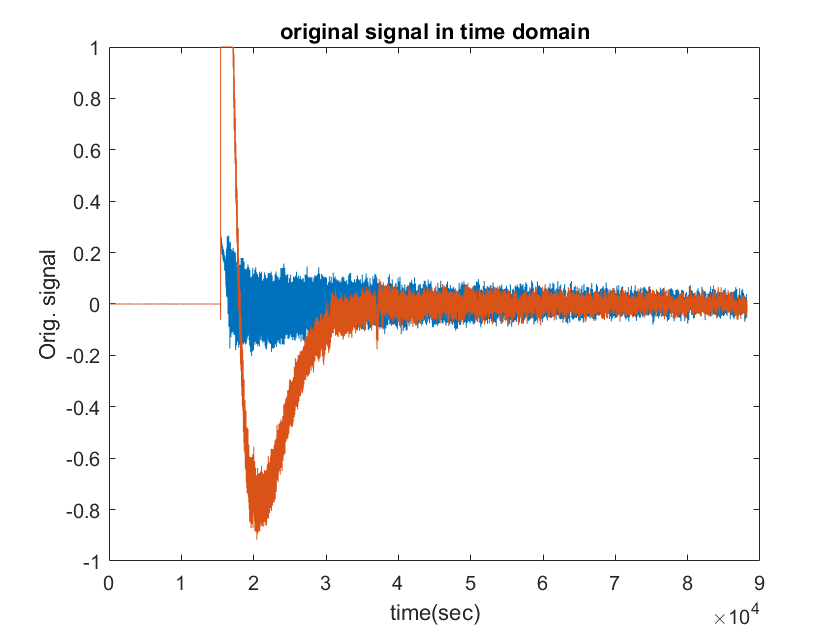

N = length(audioData);
t=0:1:N-1;
plot(t,audioData)
ylabel('Orig. signal');
xlabel('time(sec)');
title('original signal in time domain')

#### Converting original signal to frequency domain

use nextpow2 inbuilt function,

`P = nextpow2(`[`A`](https://in.mathworks.com/help/matlab/ref/nextpow2.html#btswm2v-1-A)`)` returns the exponents for the smallest powers of two that satisfy


$$2^p\ge |A|$$


for each element in `A`. By convention, `nextpow2(0)` returns zero.

You can use `nextpow2` to pad the signal you pass to [`fft`](https://in.mathworks.com/help/matlab/ref/fft.html). Doing so can speed up the computation of the FFT when the signal length is not an exact power of 2.

N = length(audioData); % Original sample length.
n = pow2(nextpow2(N)); % Transforming the length so that the number of 
% samples is a power of 2. This can make the transform computation 
% significantly faster,particularly for sample sizes with large prime 
% factors.
y = fft(audioData, n);

#### Plot original signal in frequency domain

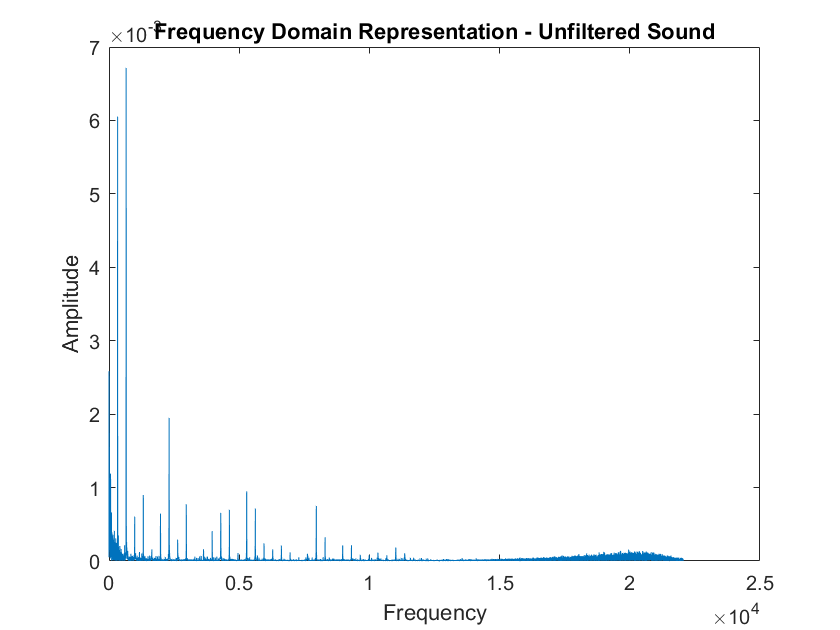


f = (0:n-1)*(Fs/n);
amplitude = abs(y)/n;
plot(f(1:floor(n/2)),amplitude(1:floor(n/2)))
title('Frequency Domain Representation - Unfiltered Sound')
xlabel('Frequency')
ylabel('Amplitude')

## 2) Applying a low pass filter to get rid of the noise

### Applying low pass butter worth filter

order = 7;
[b,a] = butter(order,1000/(Fs/2),'low');
filtered_sound = filter(b,a,audioData);

### Listening sound of filtered signal

sound(filtered_sound,Fs);

#### plotting filtered signal in time domain

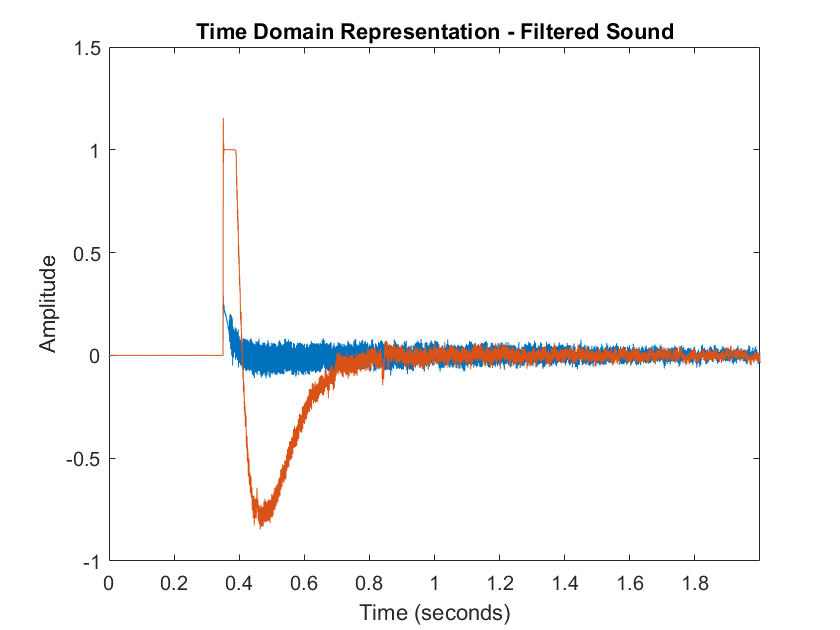

sample_period = 1/Fs;
t1 = (0:sample_period:(length(filtered_sound)-1)/Fs);
plot(t1,filtered_sound)
title('Time Domain Representation - Filtered Sound')
xlabel('Time (seconds)')
ylabel('Amplitude')
xlim([0 t1(end)])

#### Converting Filtered signal to frequency domain

use nextpow2 inbuilt function,

`P = nextpow2(`[`A`](https://in.mathworks.com/help/matlab/ref/nextpow2.html#btswm2v-1-A)`)` returns the exponents for the smallest powers of two that satisfy


$$2^p\ge |A|$$


for each element in `A`. By convention, `nextpow2(0)` returns zero.

You can use `nextpow2` to pad the signal you pass to [`fft`](https://in.mathworks.com/help/matlab/ref/fft.html). Doing so can speed up the computation of the FFT when the signal length is not an exact power of 2.

N = length(audioData); % Original sample length.
n1 = pow2(nextpow2(N)); % Transforming the length so that the number of 
% samples is a power of 2. This can make the transform computation 
% significantly faster,particularly for sample sizes with large prime 
% factors.

#### Finding fft of the filtered sound

y = fft(filtered_sound, n1);

#### Ploting filtered signal in frequency domain

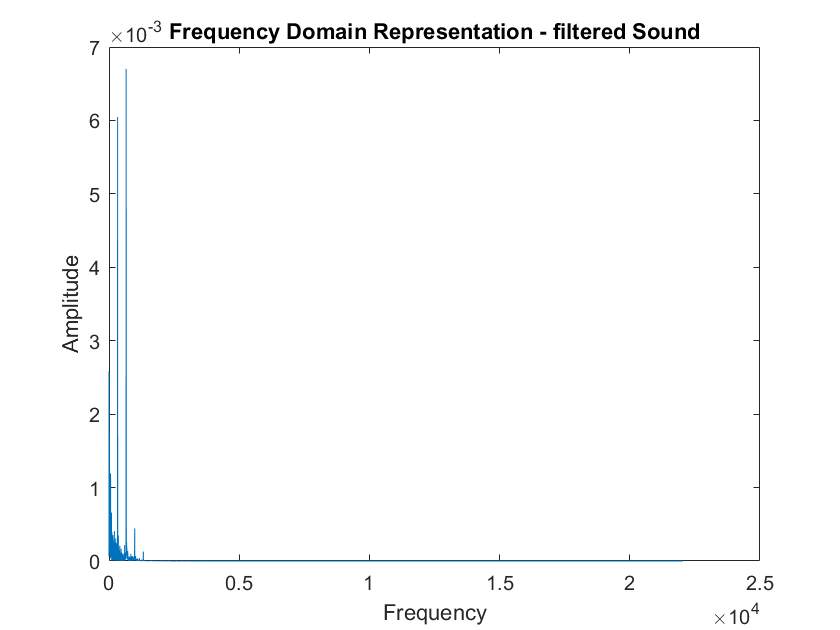

f = (0:n1-1)*(Fs/n1);
amplitude = abs(y)/n1;
plot(f(1:floor(n1/2)),amplitude(1:floor(n1/2)))
title('Frequency Domain Representation - filtered Sound')
xlabel('Frequency')
ylabel('Amplitude')

### Conclusion:-

##  In module-2 we will find the fundamental frequency of filtered signal and see that in which range of frequency set if falls by that we can identify which pich it belongs to.